## [TB]이 파일로 한 속도에서 한다음에 파일을 만들어서 속도별로 하는걸로 변경

## MCAD GetData


rpm = 8000

% dev_e10_ACLoss - Branch - 삭제할것
% MachineData From MCAD
addpwd
mcad=callMCAD
refPath='Z:\Simulation\JEETACLossValid_e10_v24\refModel\e10_UserRemesh.mot';
if ~exist(refPath,"file")
    refPath='D:\KangDH\Thesis\e10\refModel\e10_UserRemesh.mot';
end
[refDIR,FileName,~]=fileparts(refPath);
[~,curMotFilePath]=mcad.GetVariable('CurrentMotFilePath_MotorLAB')
if ~strcmp(curMotFilePath,refPath)
mcad.LoadFromFile(refPath)
end 
% get MachineData
MachineData=defMCADMachineData4Scaling(mcad)
[~,RMSCurrent]=mcad.GetVariable('RMSCurrent');
[~,MCADPhaseAdvance]=mcad.GetVariable('PhaseAdvance');
FreqE=rpm2freqE(rpm,MachineData.Pole_Number/2)

% cad Periodicity

### Fig 11. B wave form

[..\tools\loss\ACLOSS\MCAD\devCalcMCADHybridACLoss.mlx](matlab:open('..\tools\loss\ACLOSS\MCAD\devCalcMCADHybridACLoss.mlx'))

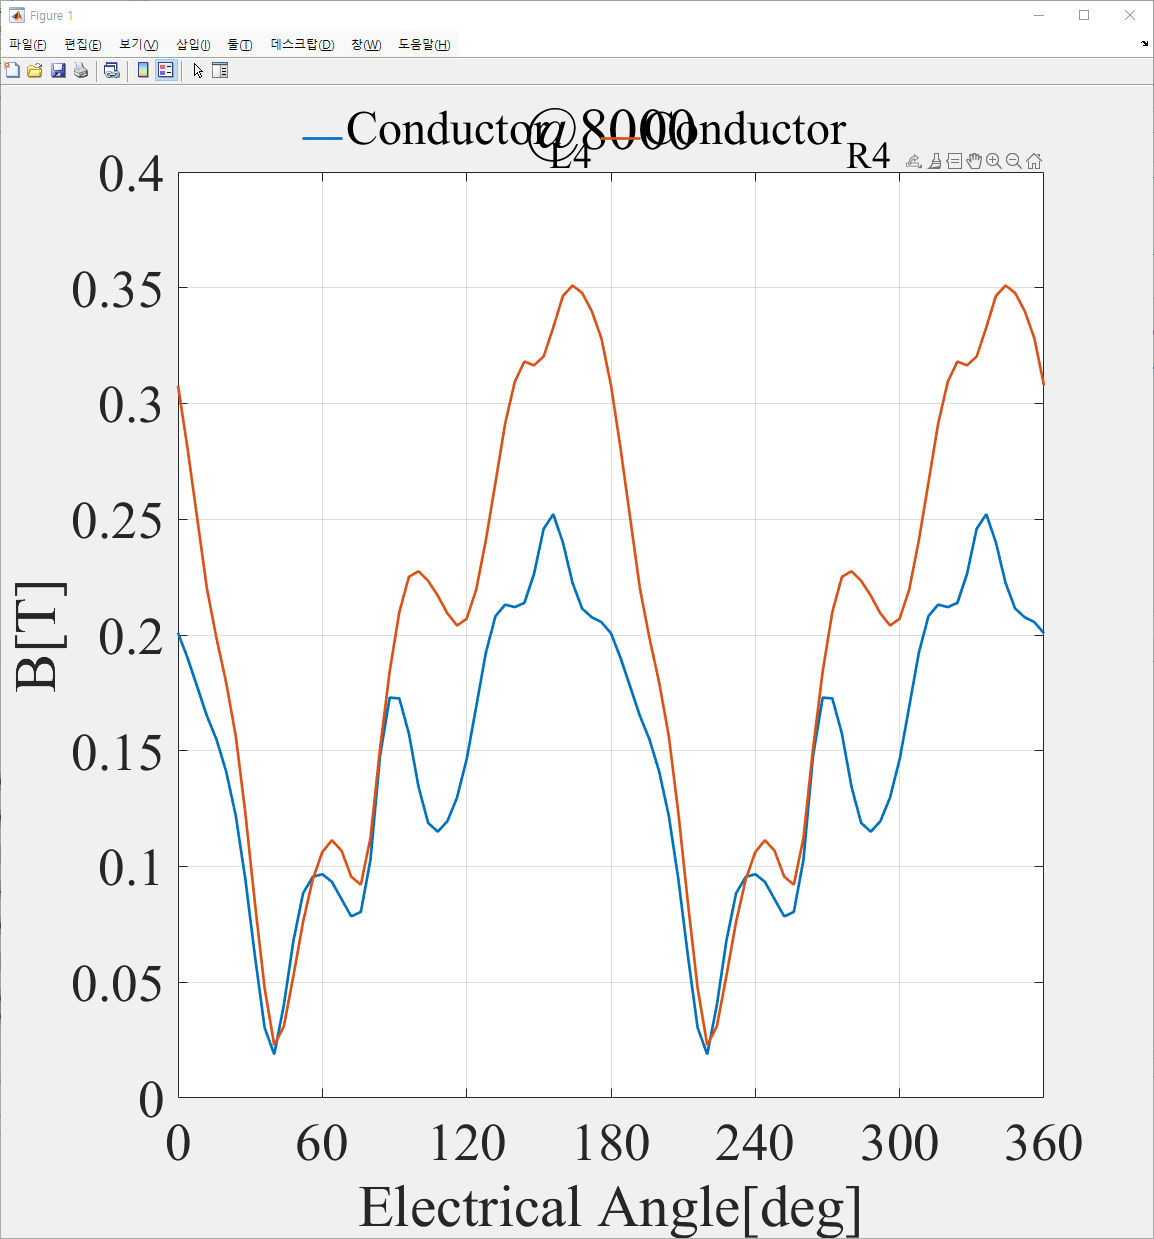

%% MotFileName
[refDIR,FileName,~]=fileparts(refPath)
% Conductor
PartName ='Stator'
settingDXFTable    =defMCADDXFExportSettingVariable(PartName);
testStatorDXFPath  =fullfile(refDIR,[FileName,PartName,'_Origin.dxf'])
settingDXFTable.CurrentValue(contains(settingDXFTable.AutomationName,'FileName'))={testStatorDXFPath};
setMcadTableVariable(settingDXFTable,mcad)
mcad.GeometryExport()
PartName ='Rotor'
settingDXFTable    =defMCADDXFExportSettingVariable(PartName);
testRotorDXFPath   =fullfile(refDIR,[FileName,PartName,'_Origin.dxf'])
settingDXFTable.CurrentValue(contains(settingDXFTable.AutomationName,'FileName'))={testRotorDXFPath};
setMcadTableVariable(settingDXFTable,mcad)
mcad.GeometryExport()
%% WriteDXF
entitiesStatorStruct        =readDXF(testStatorDXFPath)
entitiesStatorStruct        =arrayfun(@(x) setfield(x, 'layer', 'stator'), entitiesStatorStruct);
StatrDxf                    =filterEntitiesByAngle(entitiesStatorStruct, 45);
StatrDxf.entities           =entitiesStatorStruct
StatrDxf.divisions=200
plotEntitiesStruct(StatrDxf)
NewtestStatorDXFPath        =strrep(testStatorDXFPath,'Origin','');
[~,NewtestStatorDXFPath,~]  =fileparts(NewtestStatorDXFPath);
NewtestStatorDXFPath        =fullfile(refDIR,[NewtestStatorDXFPath,'_Periodic','.dxf'])
writeDXF(NewtestStatorDXFPath, StatrDxf)

### rev1에서 회전자 dxf 수정함

dxfFiles = findDXFFiles(refDIR)';
entitiesRotorStruct = readDXF(dxfFiles{1})
entitiesRotorStruct = arrayfun(@(x) setfield(x, 'layer', 'rotor'), entitiesRotorStruct);
RotorDxf = filterEntitiesByAngle(entitiesRotorStruct, 22.5);
plotEntitiesStruct(RotorDxf)
NewtestRotorDXFPath         =strrep(testRotorDXFPath,'Origin','');
[~,NewtestRotorDXFPath,~]   =fileparts(NewtestRotorDXFPath);
NewtestRotorDXFPath         =fullfile(refDIR,[NewtestRotorDXFPath,'_Periodic','.dxf']);
% delete(dxfFiles{:})
writeDXF(NewtestRotorDXFPath, RotorDxf);
dxfFiles = findDXFFiles(refDIR)';

#### dxfList2Import

dxfList2Import=defDXFList2Import(dxfFiles, 1,2)
dxfList2Import.dxfPath{1}=NewtestStatorDXFPath  ;
dxfList2Import.dxfPath{2}=NewtestRotorDXFPath  ;


## JMAG

### e10MS

e10MS

%Z:\01_Codes_Projects\git_fork_emach\tools\loss\VeriCalcHybridACLossModelwithSlotB.mlx

#### e10MS_vJuha

e10MS_Juha
%% getMeshData
FP-e10MS_Juha_skin=Proximity(current)
e10MS_Juha_skin+PpxDowell*

#### MS 같은데 mesh 플로팅

MPToolCSVFilePath='Z:/Simulation/JEETACLossValid_e10_v24/refModel/ExportMPtools/baseName.csv'
[model,pdeTriElements,pdeNodes,pdeQuadElements]  = nastran2PDEMesh(MPToolCSVFilePath);
figure(2)
% 색상을 설정합니다.
% 각 영역을 시각화하여 구분합니다.
pdegplot(model, 'FaceLabels', 'on', 'EdgeLabels', 'on');
title('Geometry with Face Labels');
numFaces = model.Geometry.NumFaces;
colors = lines(numFaces); % 각 Face에 대해 다른 색상을 생성합니다.
figure;
pdemesh(model)
x = pdeNodes(1,:);
y = pdeNodes(2,:);
hold on
quadmesh(pdeQuadElements, x, y);
centerAllFigures
% 색상을 설정합니다.
line_handles = findobj(gca, 'Type','line');
set(line_handles, 'Color', [0.8,0.8,0.8]); % 예: 검은색

Fig 9 MVP Contour

keyword='11005'; % MVP
% keyword='16001'; % B
FieldData_perStep = extractJMAGFieldVectorFromMPtoolCSV(MPToolCSVFilePath, keyword)
% csvFile=MPToolCSVFilePath
FieldData_perStep.step1
% 노드 좌표 설정

[TC]Fig 10 Slot Flux Density Contour -> Fig 8 flux density contour

addpath(genpath('Z:\01_Codes_Projects\git_SMEKlib'))
MeshPDEtoolForm=model.Mesh;
[PetFor.p,PetFor.e,PetFor.t]=MeshPDEtoolForm.meshToPet();
PetFor.t(4,:)=[]
msh=PetFor

stepNameList=fieldnames(FieldData_perStep)

for i=60:1:60
% A=Az{:,i}
A=FieldData_perStep.(stepNameList{i}).vecz;
% figure(i)
[p_plot, plotArgs] = aux_Plotting_parseInput(msh);
t = msh.t;
I = 1;

drawFluxDensity(msh, A); 
end

#### Fig 11. Slot Flux Density waveform- Jmag - manual import [Coil]

plot3DVectorB


## getMeshDat

MPToolCSVFilePath='Z:/Simulation/JEETACLossValid_e10_v24/refModel/ExportMPtools/baseName.csv'
keyword='11005'; % MVP
% keyword='16001'; % B
FieldData_perStep = extractJMAGFieldVectorFromMPtoolCSV(MPToolCSVFilePath, keyword)
% csvFile=MPToolCSVFilePath
[model,pdeTriElements,pdeNodes,pdeQuadElements]  = nastran2PDEMesh(MPToolCSVFilePath);
FieldData_perStep.step1
% 노드 좌표 설정
x = pdeNodes(1,:);
y = pdeNodes(2,:);

% 플로팅

figure;
pdemesh(model)
hold on
quadmesh(pdeQuadElements, x, y);
centerAllFigures
NodePosX=Az.PosX;
NodePosY=Az.PosX;
NodePosZ=Az.PosZ;

% [ElementID, NodeID]=devgetMeshData(app,PartIndex)
stem3(positionTable.PositionX,positionTable.PositionY,B1(:,2).Variables.^2)

% elementID 
% R4ID=


L4ID=3942
L3ID=3939
R4ID=3924
R3ID=3921
R4r=B1(num2str(R4ID),:).Variables
R4t=B2(num2str(R4ID),:).Variables
L4r=B1(num2str(L4ID),:).Variables
L4t=B2(num2str(L4ID),:).Variables
BL4abs=sqrt(L4r.^2+L4t.^2)

%% 
R4=[]
L4=[]
L3=[]
R3=[]
figure(1)
L4Data.DisplayName='Left'
L4Data.PlotType=''
L4Data.Unit='[T]'
hold on
plotXYarray([0:3:360],L4r,L4Data)
plotXYarray([0:3:360],L4t,L4Data)
plotXYarray([0:3:360],BL4abs,L4Data)
% Compare MCAd
conductorIndex=8
[shifted_signalJMAG, phase_shift] = align_signals(BL4abs, [0:3:360], opData.Wave.BCoductor{conductorIndex}.dataTable.GraphValue, opData.Wave.BCoductor{conductorIndex}.dataTable(:,2).Variables,-2, 'linear')
plotXYarray([0:3:360],shifted_signalJMAG,L4Data)


legendName=legend
legendName.String={'Left','L4r','L4t','L4abs'}
hold on
R4Data.DisplayName='Right'
R4Data.PlotType=''
plotXYarray([0:3:360],R4,R4Data)
adjustFiguresize(1,0.5)
adjustAxisLimit(1,1)


figure(2)
L3Data.DisplayName='Left'
L3Data.PlotType=''
plotXYarray([0:3:360],L3,L3Data)
hold on
R3Data.DisplayName='Right'
R3Data.PlotType=''
plotXYarray([0:3:360],R3,R3Data)
adjustFiguresize(1,0.5)
adjustAxisLimit(1,2)


## Calc $\xi$


$$
 \varphi(\xi)=\xi \frac{\sinh 2 \xi+\sin 2 \xi}{\cosh 2 \xi-\cos 2 \xi} 

$$


 
$$ \psi(\xi)=2 \xi \frac{\sinh \xi-\sin \xi}{\cosh \xi+\cos \xi}
$$



$$\xi=\alpha h_{\mathrm{c}}=h_{\mathrm{c}} \sqrt{\frac{1}{2} \omega \mu_0 \sigma_{\mathrm{c}} \frac{b_{\mathrm{c}}}{b}}$$


h_c : conductor height

b_c : conductor widht

b  : slot widht

REFdimensions=[3.7, 1.6]
b= 5.30333
bm=mm2m(b)
bc = mm2m(REFdimensions(1)); % 폭 [m]
hc = mm2m(REFdimensions(2)); % 높이 [m]
rpmList=[0:50:950 1000:1000: 20000]
freqE = rpm2freqE(rpmList,4)
coeffiXi=calckXi4EddyLoss(hc,bc,bm,freqE)
SCLdimensions=2*[3.7, 1.6]
SLCB= 5.30333*2
SLCbm=mm2m(SLCB)
SCLbc = mm2m(SCLdimensions(1)); % 폭 [m]
SCLHC = mm2m(SCLdimensions(2)); % 높이 [m]
coeffiXi_scaled=calckXi4EddyLoss(SCLHC,SCLbc,SLCbm,freqE)

figure(1)
plot(rpmList,coeffiXi,'Marker','none','Color','k','LineStyle','--','DisplayName','SCL \Xi)')
hold on
plot(rpmList,coeffiXi_scaled,'Marker','none','Color','k','LineStyle','-','DisplayName','REF \Xi)')
ax=gca
ax.XLabel.String='Rotational Speed[RPM]'
ax.YLabel.String='\Xi '
grid on
ax.XLim=[0 20000]
hold on 
formatterFigure4Paper('double','2x2')





figure(2)
psiXi   =calcProxyEffFun(coeffiXi);
varphiXi=calcSkinEffFun(coeffiXi);
psiXi_scaled   =calcProxyEffFun(coeffiXi_scaled);
varphiXi_scaled=calcSkinEffFun(coeffiXi_scaled);
Turn=4
% plot
% yyaxis left
plot(rpmList,coeffiXi,'Marker','none','Color','k','LineStyle','--','DisplayName','\xi SCL ')
hold on
plot(rpmList,coeffiXi_scaled,'Marker','none','Color','k','LineStyle','-','DisplayName','\xi REF')
plot(rpmList,psiXi_scaled,'Marker','pentagram','Color','g','LineStyle','-','DisplayName','\psi( \xi ) SCL')
hold on
plot(rpmList,psiXi,'Marker','pentagram','Color','g','LineStyle','--','DisplayName','\psi( \xi ) REF')
ax=gca
ax.YLabel.String='Resistance Factor'
yyaxis right
plot(rpmList,psiXi_scaled./psiXi,'Marker','pentagram','Color','r','LineStyle','-','DisplayName','\psi ( \xi ) Ratio')
ax.XLabel.String='Rotational Speed[RPM]'
ax.YLabel.String='SCL/REF Ratio'
grid on
ax.XLim=[0 20000]
hold on 
formatterFigure4Paper('double','2x2')

figure(3)
plot(rpmList,coeffiXi,'Marker','none','Color','k','LineStyle','--','DisplayName','\xi SCL ')
hold on
plot(rpmList,coeffiXi_scaled,'Marker','none','Color','k','LineStyle','-','DisplayName','\xi REF')
plot(rpmList,varphiXi_scaled,'Marker','square','Color','k','LineStyle','-','DisplayName','\phi ( \xi ) SCL ')
hold on
plot(rpmList,varphiXi,'Marker','square','Color','k','LineStyle','--','DisplayName','\phi( \xi ) REF')
ax=gca
ax.YLabel.String='Resistance Factor'
yyaxis right
plot(rpmList,varphiXi_scaled./varphiXi,'Marker','square','Color','r','LineStyle','-','DisplayName','\phi ( \xi ) Ratio')
ax.XLabel.String='Rotational Speed[RPM]'
ax.YLabel.String='SCL/REF Ratio'
% ax.XLabel.String='Rotational Speed[RPM]'
% ax.YLabel.String='\psi(\Xi) R_{Dc}x(Skin Effect)'
grid on
ax.XLim=[0 20000]
hold on 
formatterFigure4Paper('double','2x2')

% plot(rpmList,varphiXi_scaled./varphiXi,'Marker','square','Color','b','LineStyle','-','DisplayName','SCL \varphi(\xi)')
% plot(rpmList,psiXi_scaled./psiXi)

#### Fig 12. Hybrid AC Loss Waveform

% 선행 정보 추출
McadIndex=1
conductorType='rectangular'
[~, SimulationSmall.ShaftSpeed]    = mcad(McadIndex).GetVariable('ShaftSpeed');
[~, SimulationSmall.pole]          = mcad(McadIndex).GetVariable('Pole_Number');
[~, Copper_Width]                  = mcad(McadIndex).GetVariable('Copper_Width');
[~, Copper_Height]                 = mcad(McadIndex).GetVariable('Copper_Height');
[~, Stator_Lam_Length]             = mcad(McadIndex).GetVariable('Stator_Lam_Length');
% freqE=rpm2freqE(SimulationSmall.ShaftSpeed,SimulationSmall.pole/2)
dimensions=[Copper_Width,Copper_Height,Stator_Lam_Length]

#### calc와 mcad비교

devCalcMCADHybridACLoss 에서 

- 단일 B값으로 OuputData와 비교           - 현재 일단 안맞음

- Graph값으로 비교 - outputData와 비교 : 

-  MCAD 그래프 가져오기

-  loadMCADSimulData로 그래프(B,AC) 불러오기, 이거기준으로 비교 - 1000*48 비율했는데 이것도 잘안맞음

- jmag과도 B값 position때문에 2D로 하더라도 다름

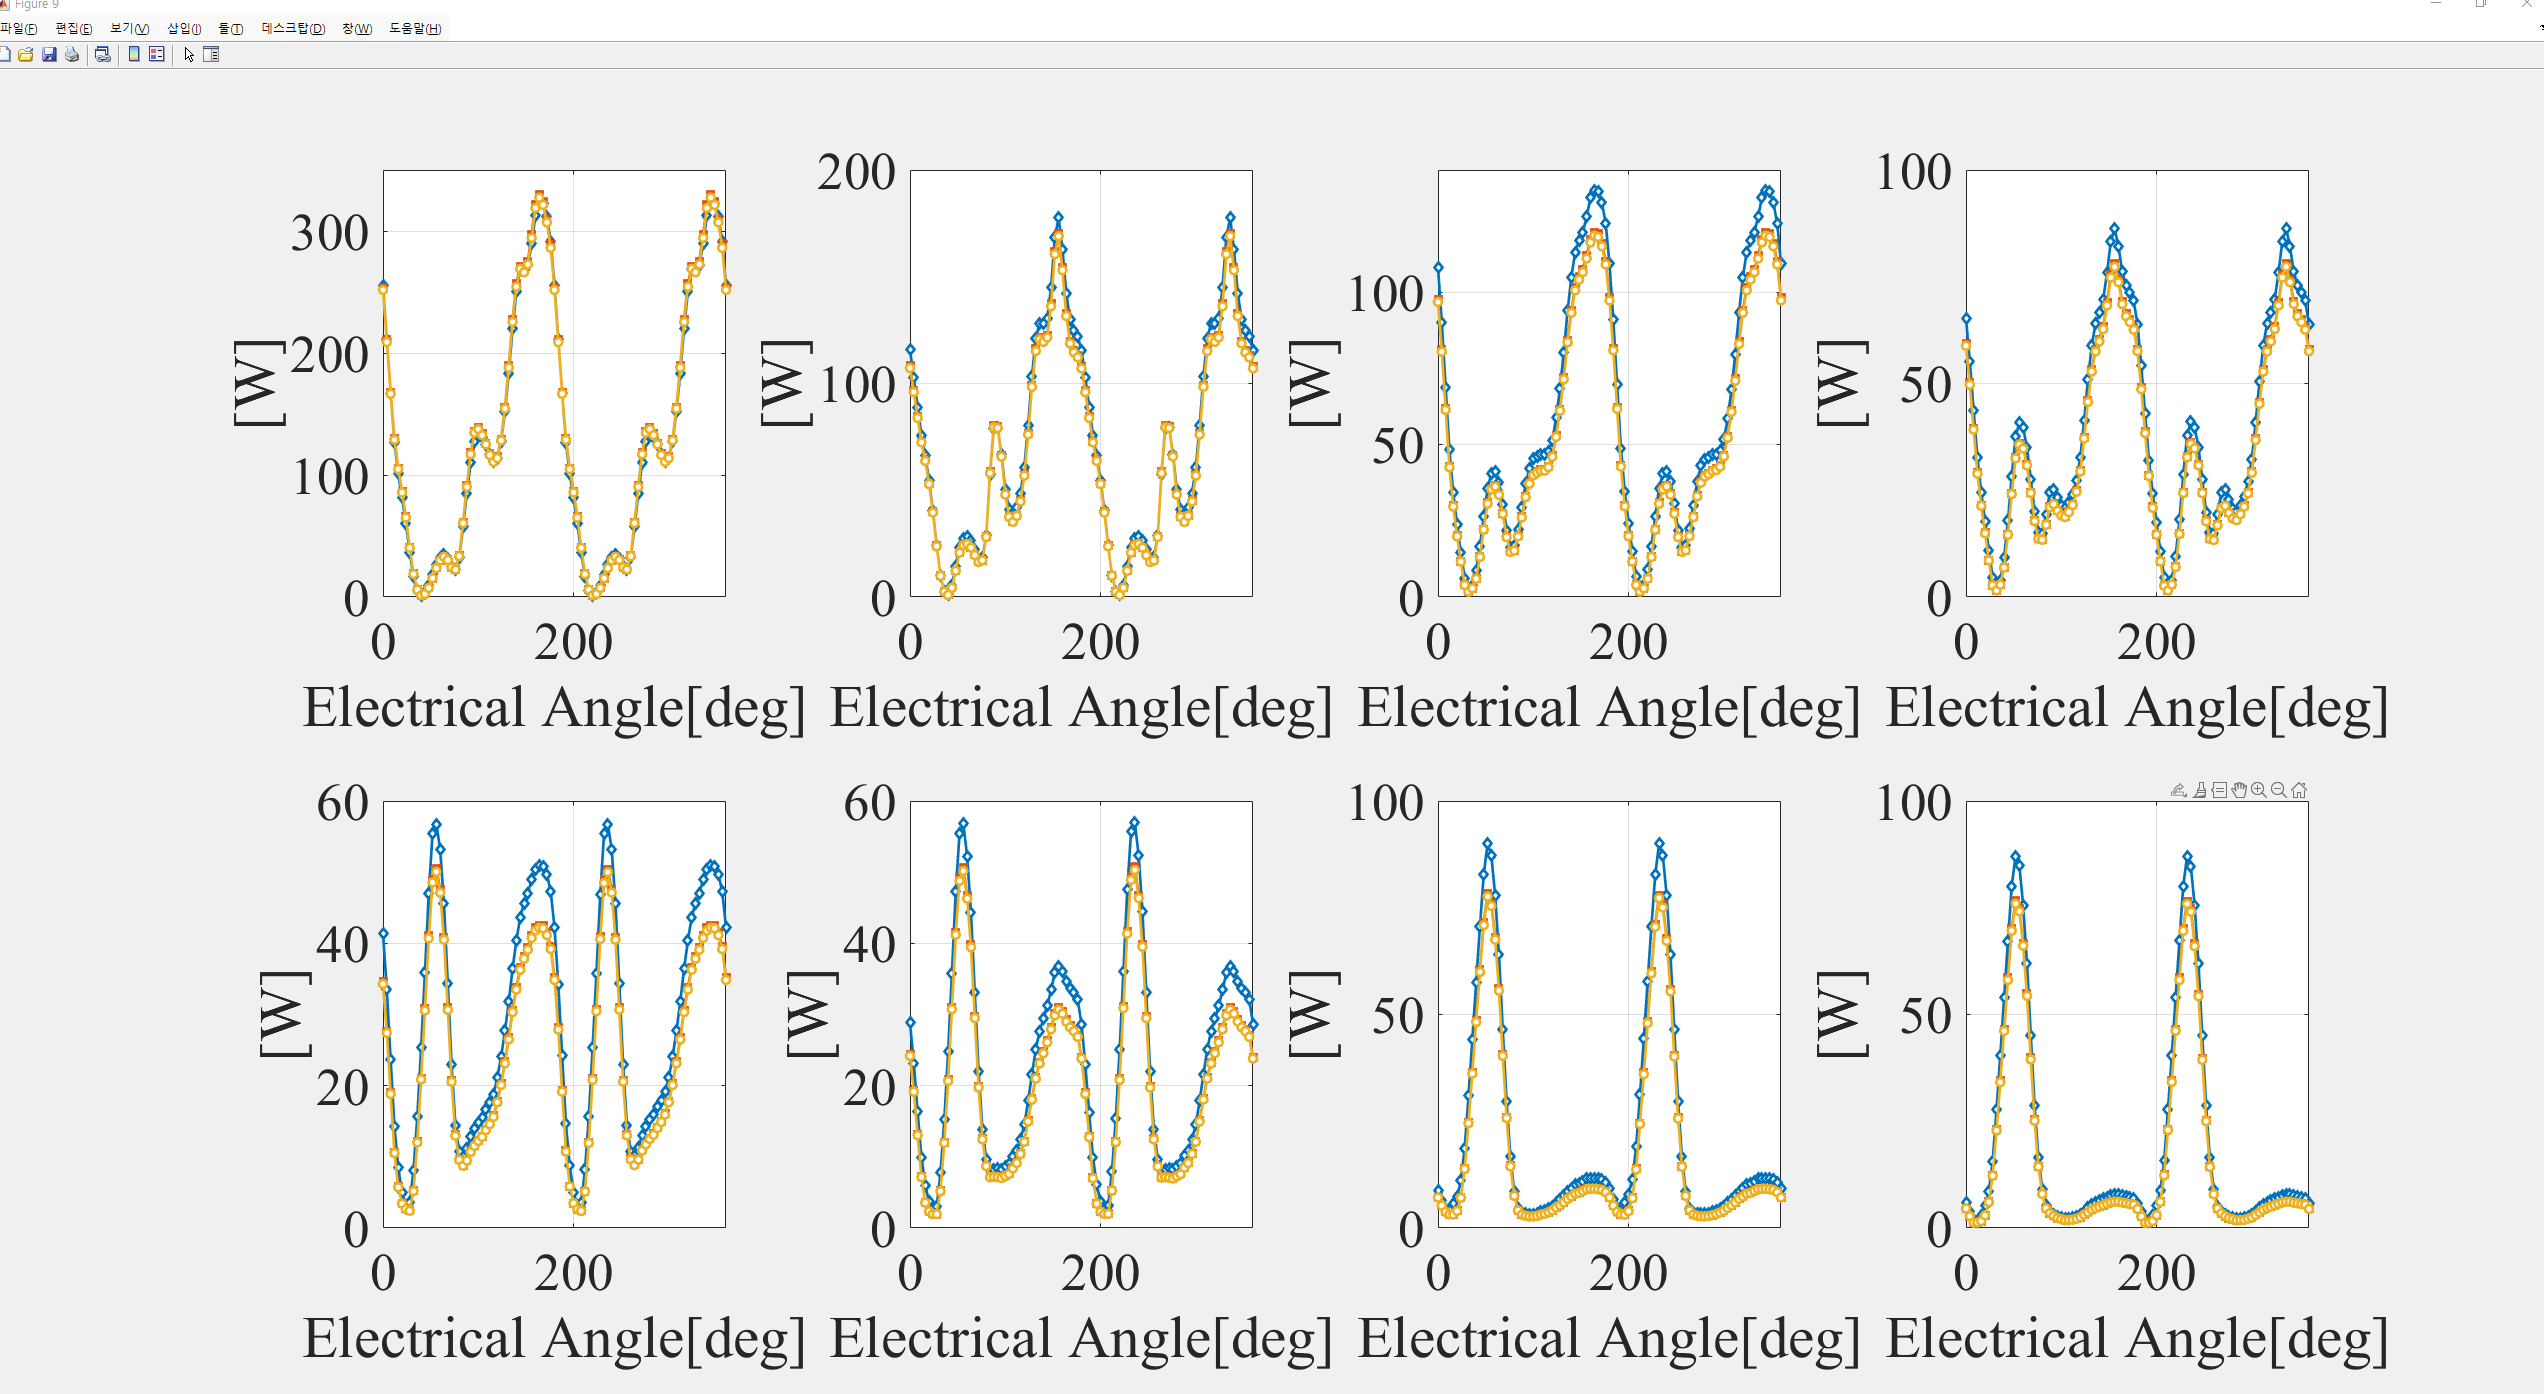

% MCAD
hybridACLossModelStr=devCalcMCADHybridACLoss(mcad)

CuboidModel          =hybridACLossModelStr.CuboidModel;
Cuboid_Width         =unique(CuboidModel.Winding_Cuboid_Width);
Cuboid_Height        =unique(CuboidModel.Winding_Cuboid_Height);
% B
for ConductorIndex=8:8
% ConductorIndex=8
ACLossCoductorWave=hybridACLossModelStr.OpDataGraph.Wave.ACLossCoductor
PMCADACLoss=ACLossCoductorWave{ConductorIndex}.dataTable.GraphValue
BWave=hybridACLossModelStr.OpDataGraph.Wave.BCoductor
BfieldMCAD=BWave{ConductorIndex}
BField=BfieldMCAD
% dimensions=[Cuboid_Width,Cuboid_Height,lactive]
[P_rect,P_1DInstant,P_1DrectG1,P1DrectG2,P_rect_nonGamma,P_rectMCAD1D,P_rec2DG1,P_rec2DG2]= calcHybridACLossWave(conductorType, dimensions, FreqE,BfieldMCAD)
figure(ConductorIndex)
plotXYarray([0:360/90:360],PMCADACLoss',P_rect1DData);
meanGraphAC=mean(PMCADACLoss')
hybridACLossModelStr.OutputDatabyMcad.PacLeft
hold on
plotXYarray([0:360/90:360],48*P_rectMCAD1D',P_rect1DData);
a=1000*48*P_rectMCAD1D
plotXYarray([0:360/90:360],48*P1DrectG2',P_rect1DData);
% shifted_signalMCAD = circshift(P_rec2DJMAG, -20);
% plotXYarray([0:3:360],shifted_signalMCAD,P_rect1DData);
% plotXYarray([0:360/90:360],48*P_1DrectG1',P_rect1DData);
% hold on
% plotXYarray([0:360/90:360],48*P_rect',P_rect1DData);
% plotXYarray([0:360/90:360],48*P_1DInstant',P_rect1DData);
end
% combineFiguresIntoSubplots

% jmag
Bfield4LayerLeft.Br         =L4r 
Bfield4LayerLeft.Bthetam    =L4t        
[P_rectJMAG,P_1DInstantJMAG,P_1DrectG1JMAG,P1DrectG2JMAG,P_rect_nonGammaJMAG,P_rectMCAD1DJMAG,P_rec2DJMAGG1,P_rec2DJMAGG2]= calcHybridACLossWave(conductorType, dimensions, FreqE,Bfield4LayerLeft)
conductorIndex=8
% [shifted_signalJMAG, phase_shift] = align_signals(P_rec2DJMAG, [0:3:360], PMCADACLoss', [0:360/90:360],-2, 'linear')
figure(conductorIndex)
hold on
shifted_signal2DJMAGG2   =48*circshift(P_rec2DJMAGG2, -21);
shifted_signal1DMCADJMAG =48*circshift(P_rectMCAD1DJMAG, -21);
shifted_signal2DJMAGG1   =48*circshift(P_rec2DJMAGG1, -21);

P_rect1DData.Unit='W'
P_rect1DData.PlotType=''
P_rect1DData.DisplayName='MS'
% plotXYarray([0:3:360],shifted_signal2DJMAGG2,P_rect1DData);
% plotXYarray([0:3:360],shifted_signal2DJMAGG1,P_rect1DData);
plotXYarray([0:3:360],shifted_signal1DMCADJMAG,P_rect1DData);
hold on
plotXYarray([0:3:360],shifted_signal2DJMAGG1,P_rect1DData);

plotXYarray([0:3:360],shifted_signal2DJMAGG2,P_rect1DData);

% legendName=legend
% legendName.String={'1D','2D','MCAD'}

#### Locus 그려서 1D로 할지 2D로 할지 결정

plotVectorFieldLocus(positionTable, BxMatrix, ByMatrix)

### e10MQS

e10MQS
% Z:\01_Codes_Projects\git_fork_emach\tools\jmag\dev_e10_ACLoss.mlx


#### Circuit Modeling

% [TC]winding From MCAD
windingPatternTxtPath ='Z:\Simulation\JEETACLossValid_e10_v24\refModel\e10_8p48s2Para4turn.txt'
[McadWindingPatternTable, MachineInfo]=readMCADWindingPatterTXT(windingPatternTxtPath)
outputPath=convertMCAD2JmagWireTable(McadWindingPatternTable)
% generate Winding Table

%

% 3Phase Circuit Component
InputCurrentData.pole=8
InputCurrentData.slot=48
InputCurrentData.ParallelNumber=2
PhaseStruct = mkConductorCircuit(8,48,2, CoilList, app, 70)
PhaseStruct(1).ParaStruct.ComponentTable
ConductorPartTable
% Input Circuit Component
InputPosition=[-17,56]
[compObj,InstanceObj]=mkJmag3PhaseSinInput(app,InputPosition)
TerminalPositionList{1}=[InputPosition(1)+2,InputPosition(2)+2];
TerminalPositionList{2}=[InputPosition(1)+2,InputPosition(2)];
TerminalPositionList{3}=[InputPosition(1)+2,InputPosition(2)-2];

% Connect
for PhaseIndex=1:3
      %% Connect each phase to Input
        StartPosition=PhaseStruct(PhaseIndex).StartPosition
        TerminalPosition=TerminalPositionList{PhaseIndex};
        curCircuitObj.CreateWire(StartPosition(3)-2, StartPosition(4), TerminalPosition(1),StartPosition(4));
        curCircuitObj.CreateWire(TerminalPosition(1),StartPosition(4), TerminalPosition(1),TerminalPosition(2));
end


### e10MQS_wireTemp

% \mlxperPJT\JEET\e10MQS_WireTemplate.m

## FP Method

% MS > FP > Noload & Armatuare Only
% A > J 
% 


## 데이터 비교 

deve10_Comparison_MQS_MS
deve10_JMAG_MQS_ACLoss
deve10_JMAG_MS_ACLoss


% B,W Graph=AnalysisType(2)*DataType(2)* 2(Load) * 2(Model) *2(Layer-4,3 Layer) =32 % 
AnalysisType ={'MS','MQS'};
DataType     ={'probeB','LossByJ','probeJ','Loss[W]S'};
StudyType    ={'_Load','NoLoad'};
ModelType    ={'ref','SC'};
LayerNumber  ={'4','3'};
LoadNumBWGraph   =length(AnalysisType)*(length(DataType)-2)*(length(StudyType)-1)*length(ModelType)*length(LayerNumber);
NumTotalGraph    =LoadNumBWGraph/length(ModelType)/length(AnalysisType);  % Load, probeB, LossyByJ, LayerNumber
% figure Num =Total Graph/(Model-with break yaxis) = 6
%+ NoLoad Graph - 
NoLoadNumBWGraph   =length(AnalysisType)*(length(DataType)-1)*(length(StudyType)-1)*(length(ModelType)-1)*length(LayerNumber);
addNoloadBW        =NoLoadNumBWGraph/length(AnalysisType);  % Noload, ProbeB, LossByJ, LayerNumber,
% Add Current Density
NoLoadNumJGraph   =(length(AnalysisType)-1)*(length(DataType)-2)*(length(StudyType)-1)*(length(ModelType))*length(LayerNumber);
addNoloadJ        =NoLoadNumJGraph/length(ModelType);  % Noload, ProbeJ, LayerNumber,
%% 
LoadNumBWGraph   =length(AnalysisType)*(length(DataType)-3)*(length(StudyType)-1)*length(ModelType)*length(LayerNumber);
NumTotalGraph    =LoadNumBWGraph/length(ModelType)/length(AnalysisType);  % Load, probeB, LossyByJ, LayerNumber


## MS_ACLoss

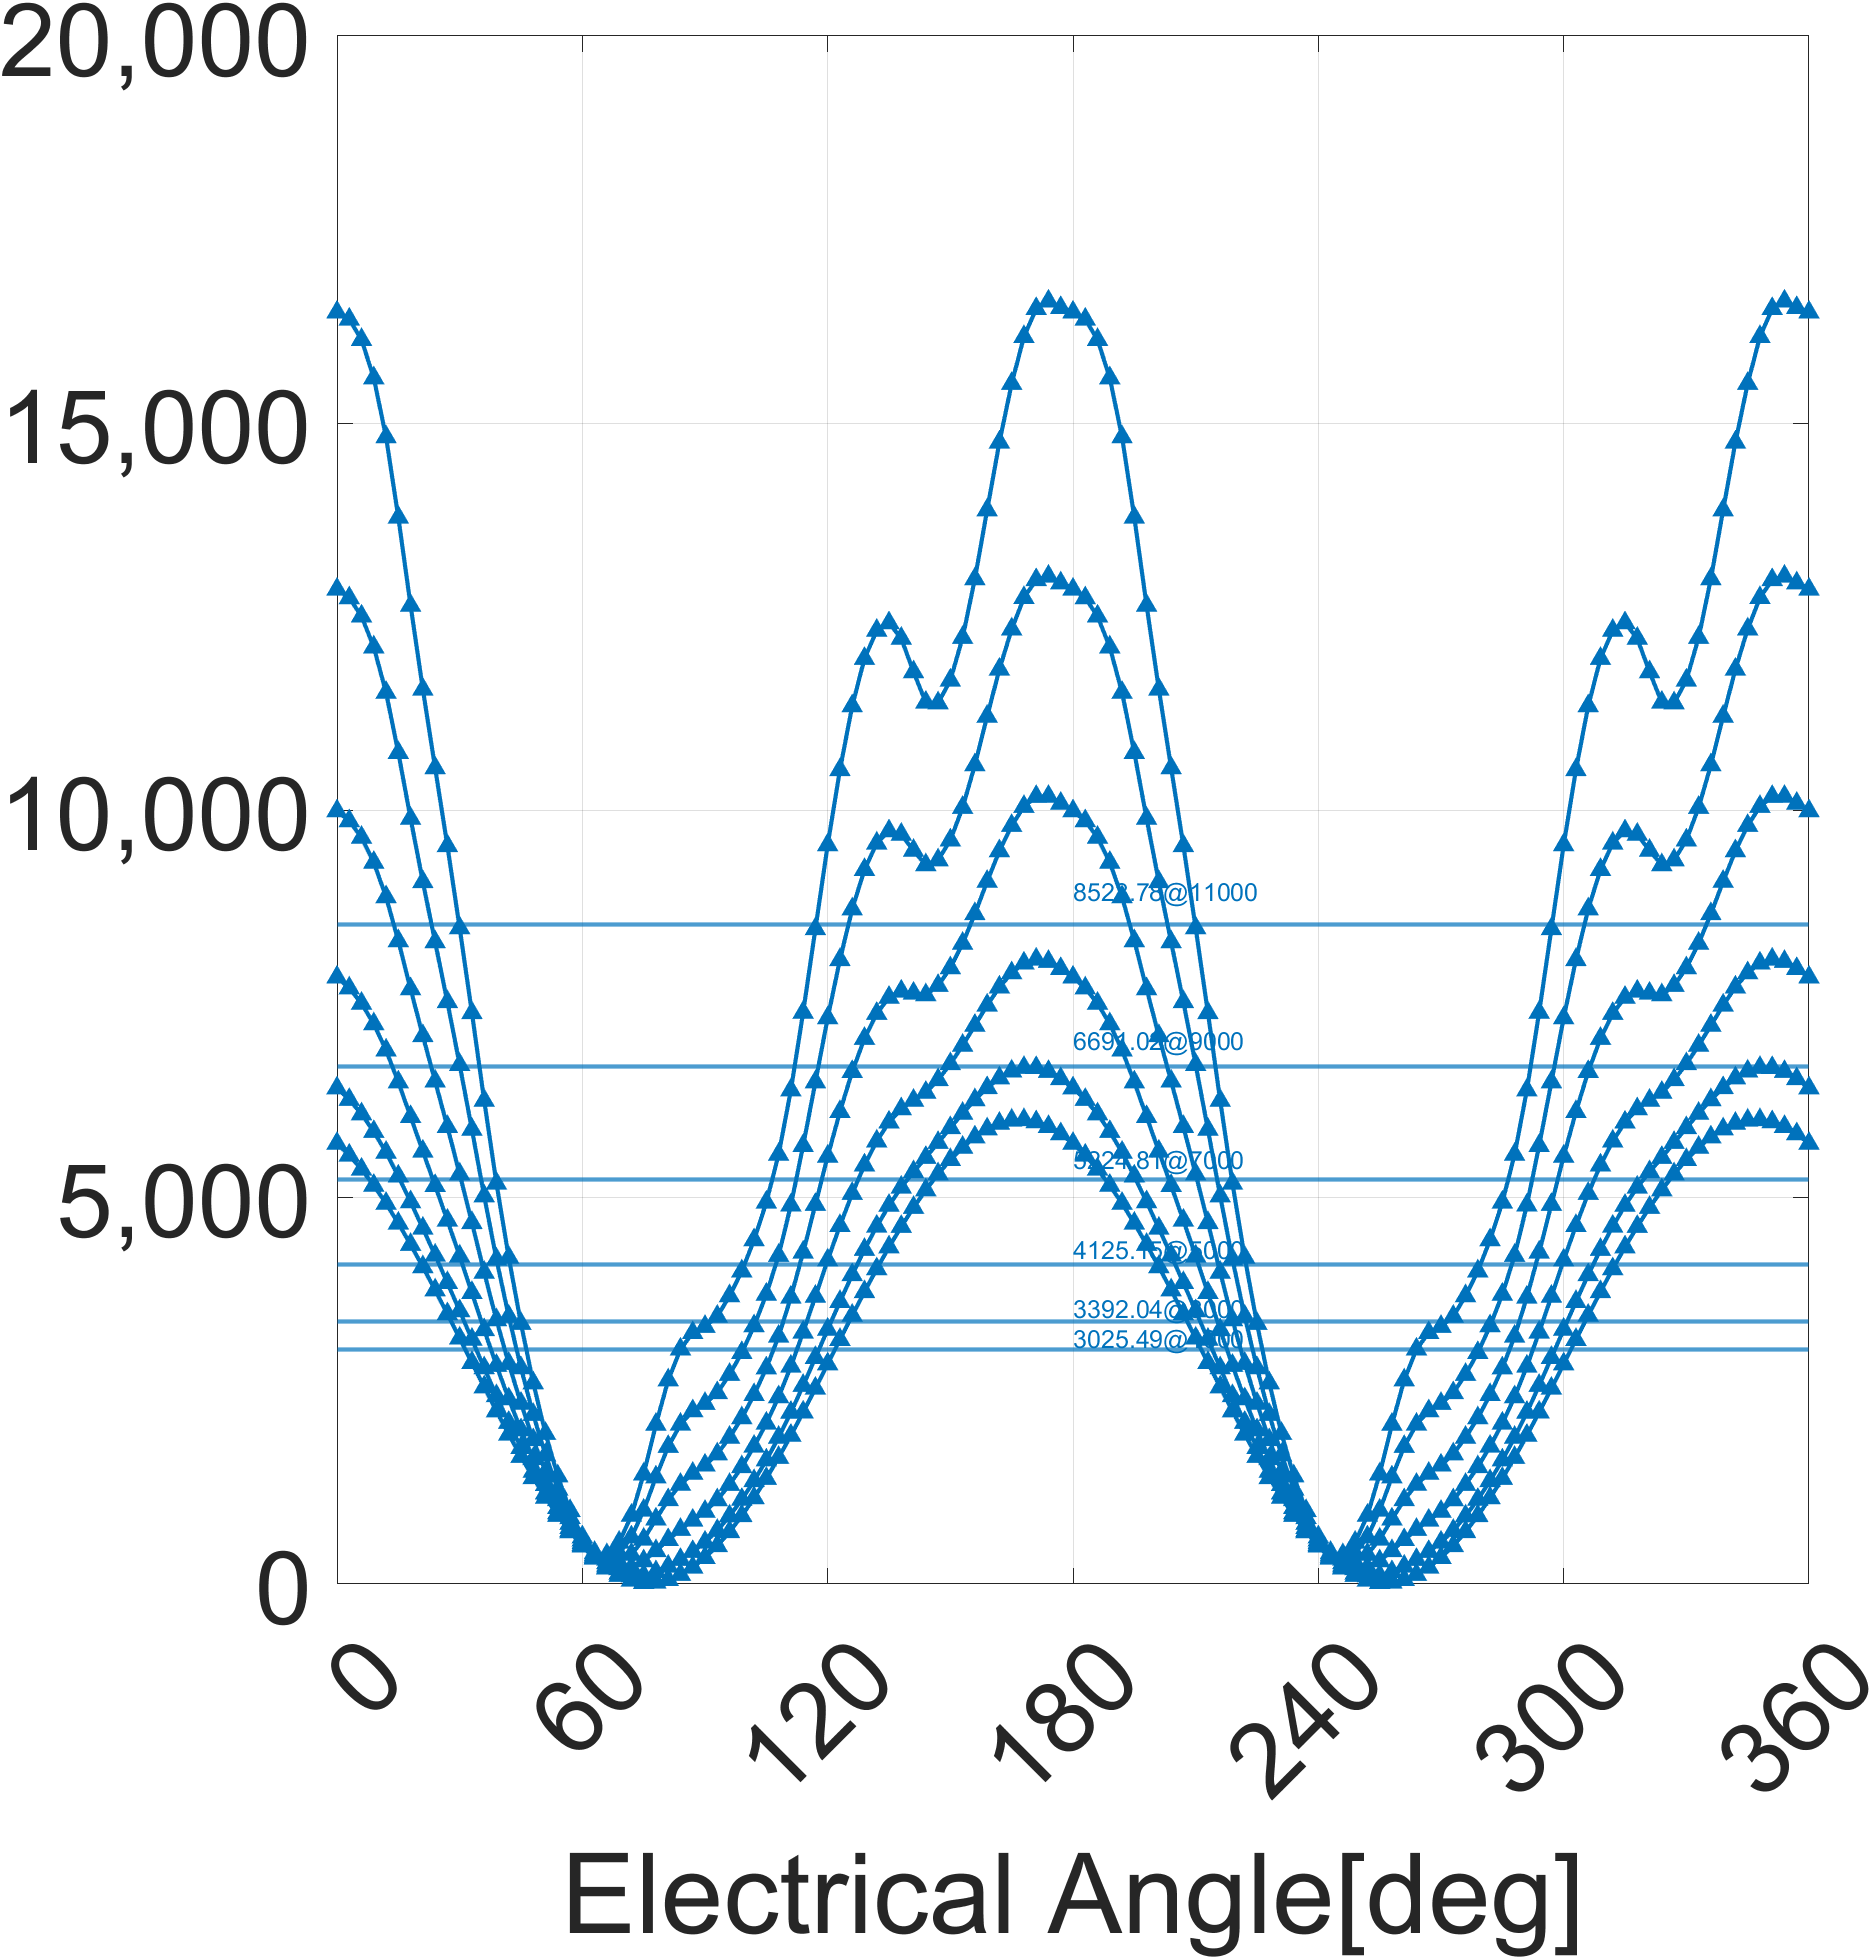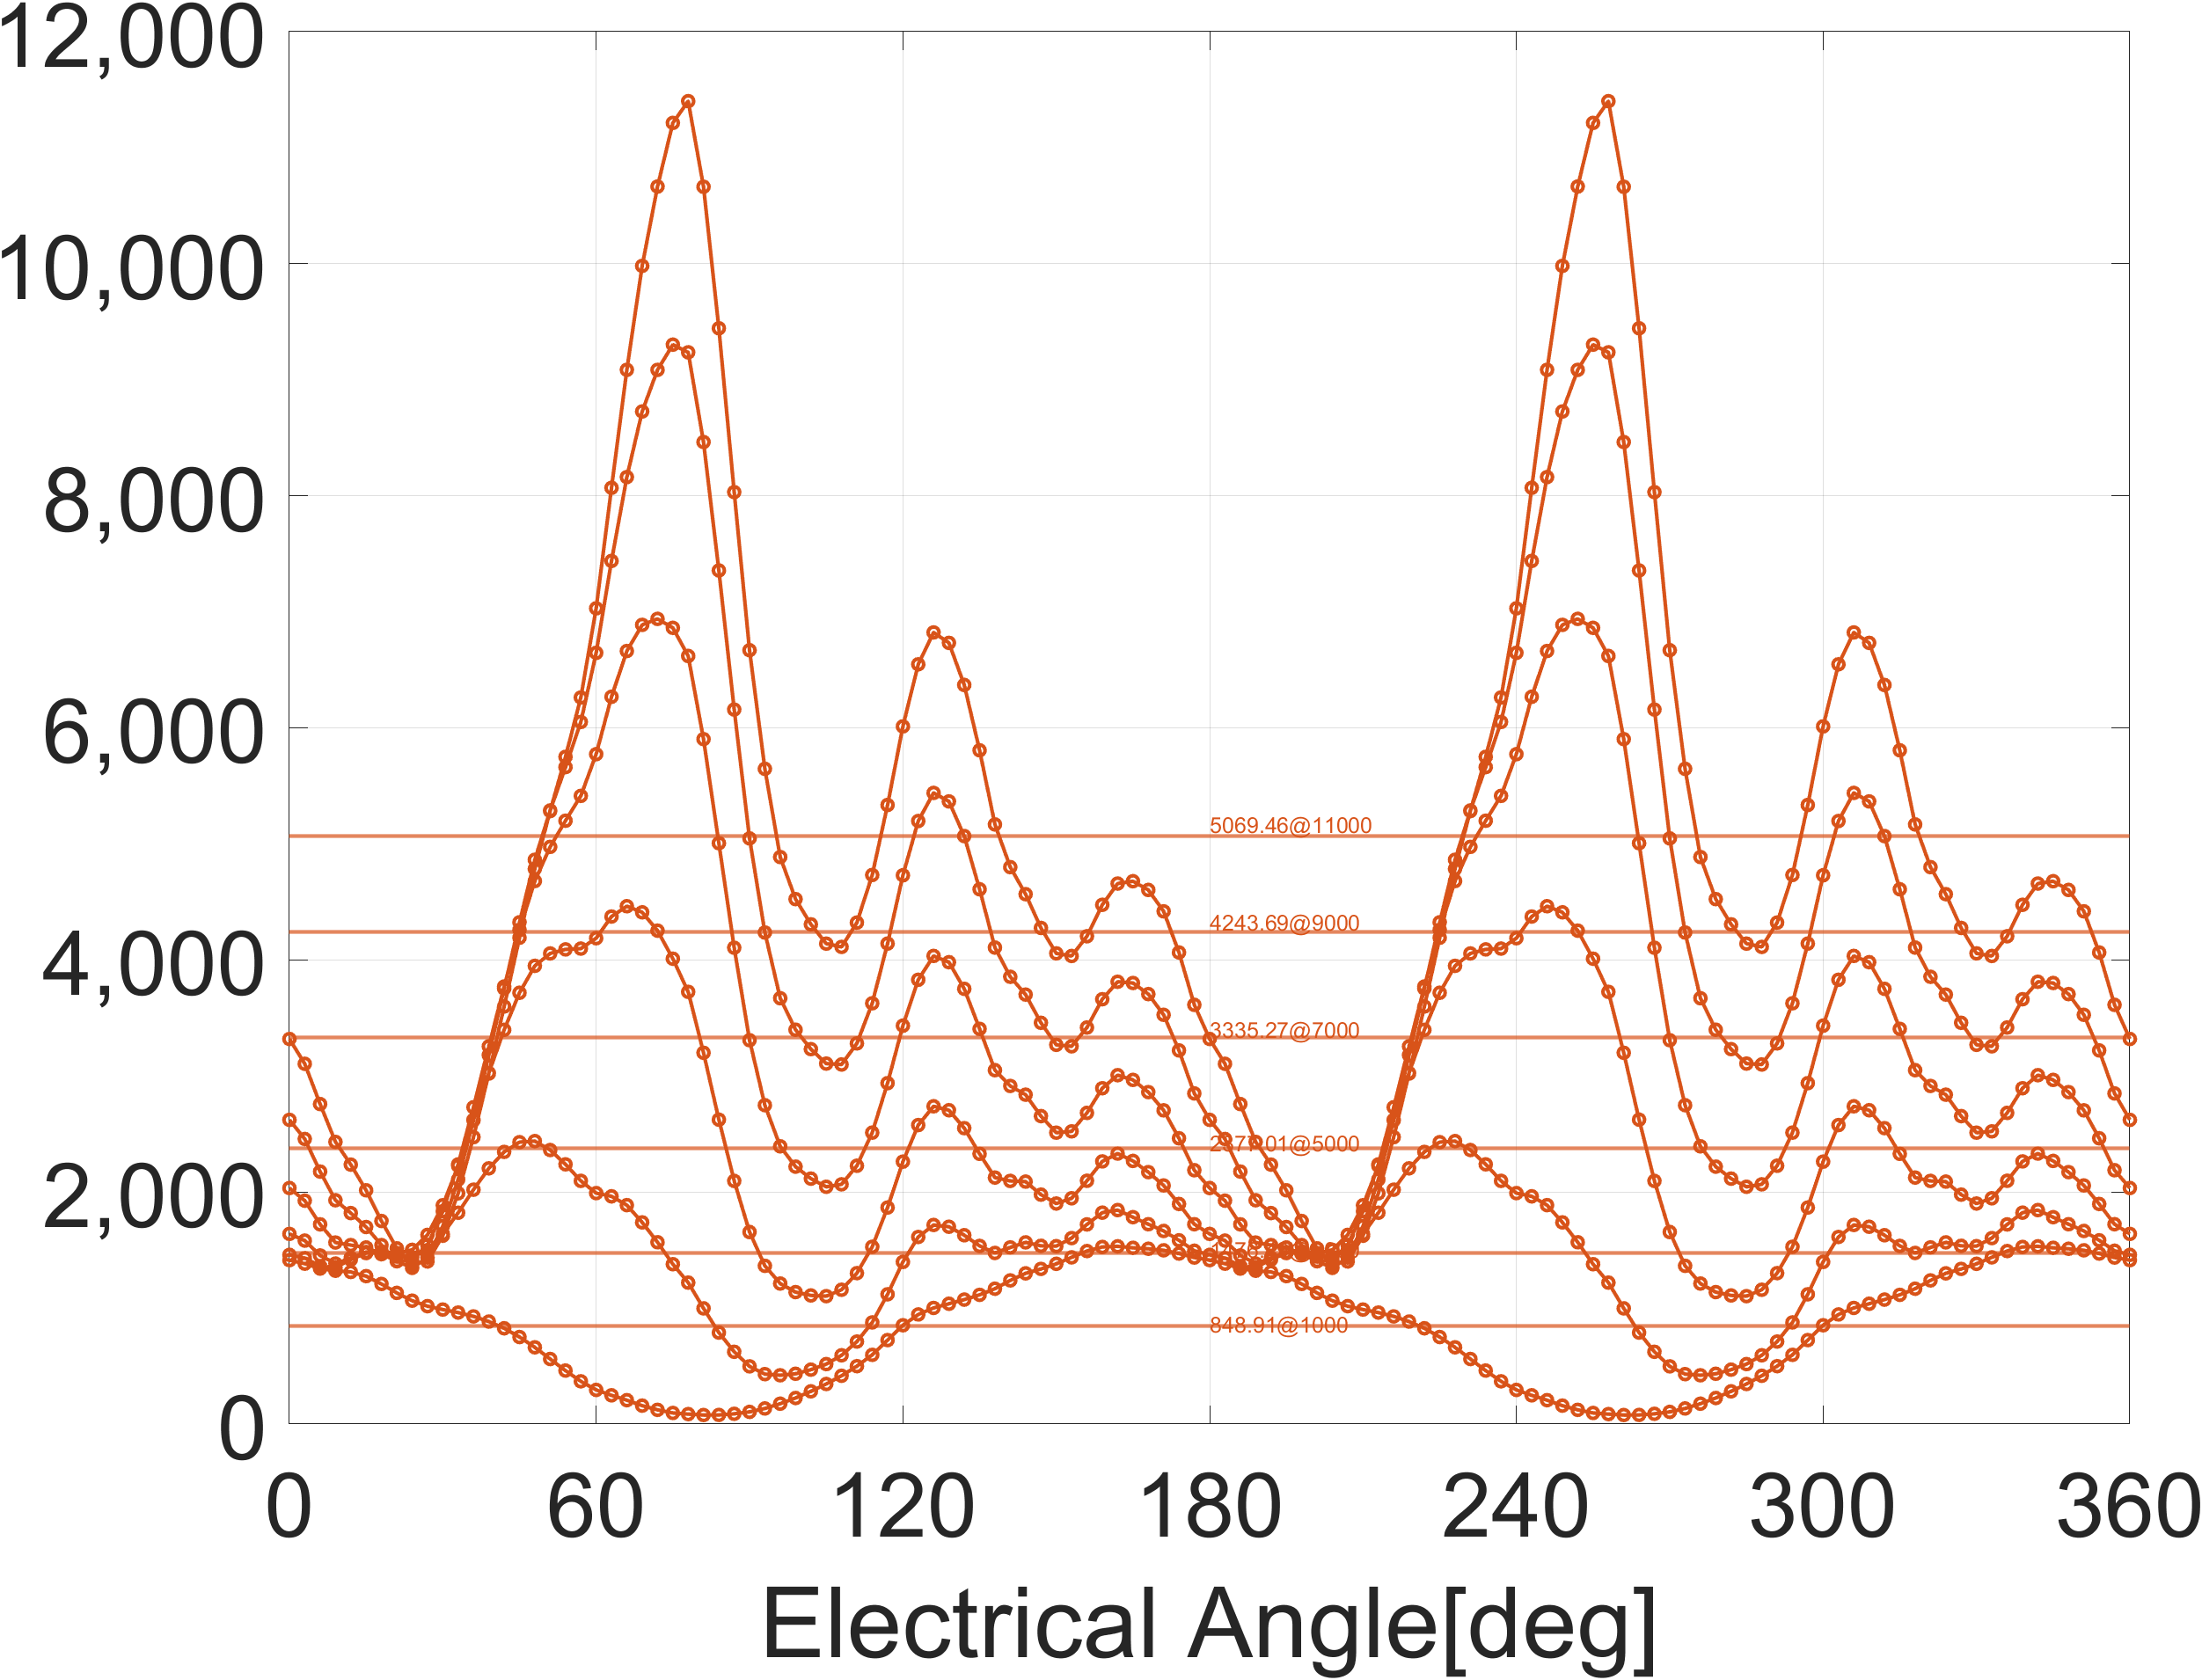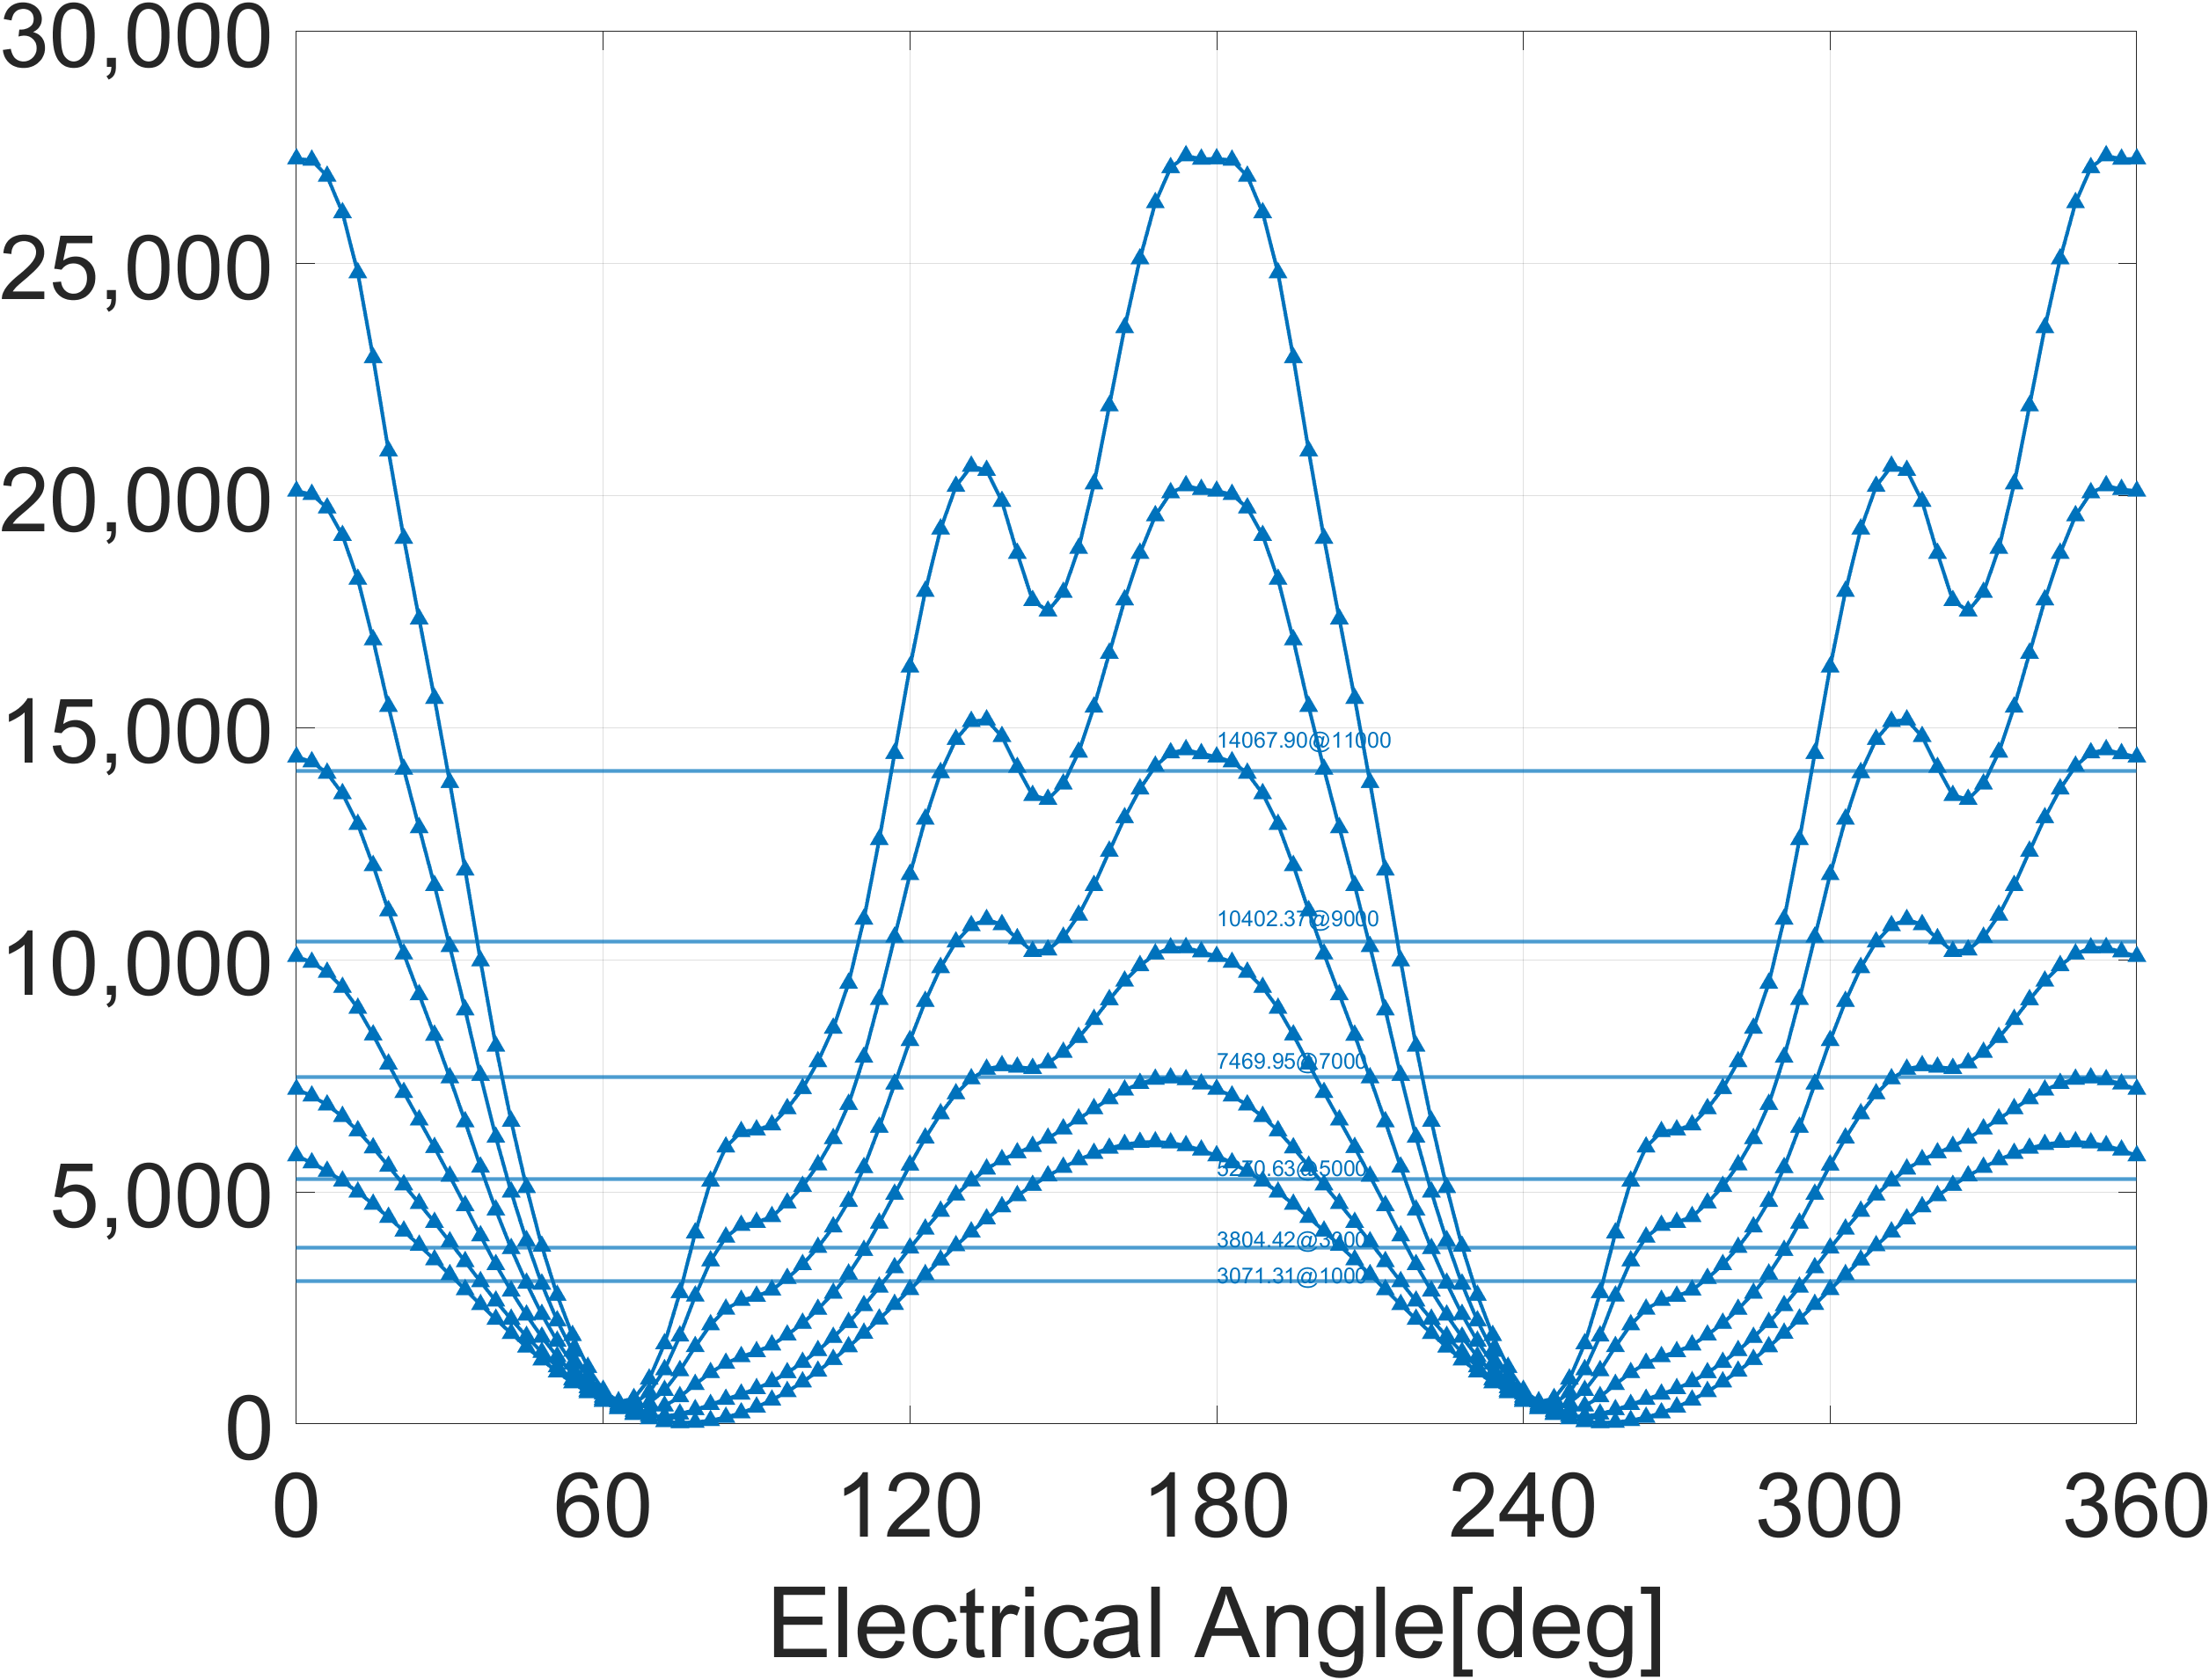

## Pyleecan

[SCIdrms,SCIqrms]=pkgamma2dq(460*2,43.3)

유효하지 않은 표현식입니다. 누락되거나 불필요한 문자가 있는지 확인하십시오.


refproxLossListPath='Z:\Simulation\JEETACLossValid_e10_v24\refModel\refproxLossList.mat'
refJouleLossListPath='Z:\Simulation\JEETACLossValid_e10_v24\refModel\refJouleLossList.mat'
SCproxLossListPath ='Z:\Simulation\JEETACLossValid_e10_v24\SLFEA\SCproxLossList.mat'
SCJouleLossListPath='Z:\Simulation\JEETACLossValid_e10_v24\SLFEA\SCjouleLossList.mat'


refproxLoss =load(refproxLossListPath);
refJouleLoss=load(refJouleLossListPath);
SCproxLoss  =load(SCproxLossListPath );
SCJouleLoss =load(SCJouleLossListPath);

speedList=[1000:2000:14000];

plot(speedList,refJouleLoss.refJouleLossList/1000,'DisplayName','refJoule')
hold on
% plot(speedList,refproxLoss.refproxLossList/1000,'DisplayName','refProx')
% plot(speedList,SCproxLoss.SCproxLossList/1000  ,'DisplayName','SCProx')
plot(speedList,SCJouleLoss.SCjouleLossList/1000  ,'DisplayName','SCJoule')
% Total Winding
refWindingLoss=refJouleLoss.refJouleLossList/1000+refproxLoss.refproxLossList/1000;
SCWindingLoss=SCproxLoss.SCproxLossList/1000+SCJouleLoss.SCjouleLossList/1000


speedList=[1000:2000:14000];

plot(speedList,refWindingLoss,'o-','DisplayName','Hybridref Winding Loss')
hold on
plot(speedList,SCJouleLoss.SCjouleLossList/1000  ,'DisplayName','SCJoule')

% plot(speedList,refWindingLoss,'o-','DisplayName','Hybridref Winding Loss')

% plot(speedList,SCWindingLoss,'^-','DisplayName','SC Winding Loss')


## 비율비교 Pyleecan


plot(speedList,(SCECLoss(:,2)/1000),'Marker','+','Color','k','LineStyle','-','DisplayName','MQS SCL')
hold on
yyaxis left
plot(speedList,(refECLoss(:,2)/1000),'Marker','+','Color','k','LineStyle','--','DisplayName','MQS REF')
ax=gca
ax.YLabel.String='Joule Loss(DC+AC)[kW]'

plot(speedList,SCJouleLoss.SCjouleLossList/1000,'Marker','o','Color','b','LineStyle','-','DisplayName','MS-HYB SCL')
plot(speedList,refJouleLoss.refJouleLossList/1000,'Marker','o','Color','b','LineStyle','--','DisplayName','MS-HYB REF')

yyaxis right
plot(speedList,SCJouleLoss.SCjouleLossList./refJouleLoss.refJouleLossList,'Marker','+','Color','r','LineStyle','-.','DisplayName','MS-HYB SCL/REF Ratio')
hold on
plot(speedList,(SCECLoss(:,2)/1000)./(refECLoss(:,2)/1000),'Marker','o','Color','r','LineStyle','-.','DisplayName','MQS SCL/REF Ratio')

% % plot(rpmList,psiXi_scaled./psiXi,'DisplayName','MS Hybrid SC vs ref Winding Loss Ratio')
hold on,
ax.XLabel.String='Rotational Speed[RPM]'
ax.YLabel.String='Joule Loss Ratio'
grid on
ax.XLim=[1000 13000]
hold on 
formatterFigure4Paper('double','2x2')

% plot(rpmList,(psiXi_scaled+varphiXi_scaled)./(psiXi+varphiXi),'DisplayName','MS Hybrid SC vs ref Winding Loss Ratio')

AC Loss비율비교

4436.737297297296
DCLoss=460.^2*3*RphActive;
SLCMQSACLoss=(SCECLoss(:,2)/1000-DCLoss/1000)
REFMQSACLoss=(refECLoss(:,2)/1000-DCLoss/1000)
figure(2)
plot(speedList,SLCMQSACLoss,'Marker','+','Color','k','LineStyle','-','DisplayName','MQS SCL AC')
hold on
plot(speedList,REFMQSACLoss,'Marker','+','Color','k','LineStyle','--','DisplayName','MQS REF')
yyaxis right
hold on
plot(speedList,SLCMQSACLoss./REFMQSACLoss,'Marker','o','Color','r','LineStyle','-.','DisplayName','MQS SCL/REF Ratio')
hold on,
ax.XLabel.String='Rotational Speed[RPM]'
ax.YLabel.String='Joule Loss Ratio'
grid on
ax.XLim=[1000 13000]
hold on 
formatterFigure4Paper('double','2x2')


SLCMSACLoss=SCJouleLoss.SCjouleLossList/1000-4436.737297297296/1000;
REFMSACLoss=refJouleLoss.refJouleLossList/1000-4436.737297297296/1000;
plot(speedList,SLCMSACLoss,'Marker','o','Color','b','LineStyle','-','DisplayName','MS-HYB SCL')
hold on
plot(speedList,REFMSACLoss,'Marker','o','Color','b','LineStyle','--','DisplayName','MS-HYB REF')

plot(speedList,SLCMSACLoss./REFMSACLoss,'Marker','o','Color','r','LineStyle','-.','DisplayName','MQS SCL/REF Ratio')


MeanLine MS

for speedIndex=1:length(speedList)-1
    speed=speedList(speedIndex);
    scatter(speed,[meanLineMS{speedIndex}{1}]/1000,'k')
    hold on
    scatter(speed,[SCACmeanLineMS{speedIndex}{1}]/1000,'k')
end



## Hybrid 1D + Juha Joule Loss

for speedIndex=1:6
    refLoss.Hyb1DJuhaJouleList(speedIndex)=6*(meanLineMS{speedIndex}{1}-DCLoss)+refJouleLoss.refJouleLossList(speedIndex)
    % SCLoss.Hyb1DJuhaJouleList(speedIndex)=6*(SCACmeanLineMS{speedIndex}{1}-DCLoss)+SCJouleLoss.SCjouleLossList(speedIndex)
    SCLoss.G12DList(speedIndex)=mean(SCTotalACLossPerMethod{speedIndex}{3})
    SCLoss.OneDList(speedIndex)=mean(SCTotalACLossPerMethod{speedIndex}{1})
    SCLoss.OneD2List(speedIndex)=mean(SCTotalACLossPerMethod{speedIndex}{2})
    SCLoss.Hyb1DJuhaJouleList(speedIndex)=SCLoss.OneDList(speedIndex)+SCJouleLoss.SCjouleLossList(speedIndex)
    SCLoss.JuhaLossList(speedIndex)=SCproxLoss.SCproxLossList(speedIndex)/5.3477+SCJouleLoss.SCjouleLossList(speedIndex)
end

refDimension.w=3.7;
refDimension.h=1.6;
refDimension.w.^2/refDimension.h.^2
(2*refDimension.w).^2/(2*refDimension.h).^2
speedList=[1000:2000:13000];

plot(speedList(1:6),refLoss.Hyb1DJuhaJouleList/1000,'o-','DisplayName','Hybridref Winding Loss')
hold on
plot(speedList(1:6),SCLoss.Hyb1DJuhaJouleList/1000,'^-','DisplayName','Hybrid SC Winding Loss')
% plot(speedList(1:6),SCproxLoss.SCproxLossList(1:6)/1000/5.3477  ,'DisplayName','SCProx')

plot(speedList(1:6),SCLoss.JuhaLossList/1000,'^-','DisplayName','JuHa SC Winding Loss')


hold on 
plot(speedList(1:6),SCJouleLoss.SCjouleLossList(1:6)/1000,'V-','DisplayName','Hybrd SC Joule Loss')

plot(speedList(1:6),SCLoss.OneDList/1000,'DisplayName','OneD')

plot(speedList(1:6),SCLoss.G12DList/1000,'DisplayName','G12D')
% plot(speedList,refECLoss(:,2)/1000,'DisplayName','refAllLoss')
% hold on
% plot(speedList,SCECLoss(:,2)/1000,'DisplayName','SCAllLoss')

## MQS

targetName='Total';
speedList=[1000:2000:15000];
TotalJoule4Case=cell(length(speedList),1);
for TableIndex=2:2
    for caseIndex=1:height(MQSRefLoadTable)
    speed2Plot=speedList(caseIndex);    
    table2Plot=MQSRefLoadTable{caseIndex,TableIndex}{1};
    varNames=table2Plot.Properties.VariableNames;
        if any(contains(varNames,targetName,"IgnoreCase",true))
        % calc
        table2plotPerVarNames=table2Plot(:,varNames);
        JouleAvgTablCell4Case{caseIndex,1}=varfun(@mean ,table2plotPerVarNames(end-120:end,:),"OutputFormat","table");
        JouleAvgTablCell4Case{caseIndex,2}=JouleAvgTablCell4Case{caseIndex,1}(:,end).Variables;
        end
    end
end


% plot 양식
% figure
yyaxis left
% LossLine(1)=plot(speedList,[JouleAvgTablCell4Case{:,2}]/1000,'*-')
hold on
refACLoss=[JouleAvgTablCell4Case{:,2}]/1000-refDCLoss/1000;
% LossLine(1)=plot(speedList,refACLoss,'*-','DisplayName','ref AC Loss');
LossLine(1)=plot(speedList,[JouleAvgTablCell4Case{:,2}]/1000,'*-','DisplayName','ref Winding Loss');

xlabel('Rotor Speed[RPM]')
% ylabel('Total AC Loss[kW]')
ylabel('Total Winding Loss[kW]')

LossLine(1).Color='K';

formatterFigure4Paper(2, '1x1')
hold on
% MQS SC 
% Average - along last 120Step (Total)
targetName='Total'
speedList=[1000:2000:15000];
TotalJoule4Case=cell(length(speedList),1);
for TableIndex=2:2
    for caseIndex=1:height(TargetTable)
    speed2Plot=speedList(caseIndex);    
    table2Plot=TargetTable{caseIndex,TableIndex}{1};
    varNames=table2Plot.Properties.VariableNames;
        if any(contains(varNames,targetName,"IgnoreCase",true))
        % calc
        table2plotPerVarNames=table2Plot(:,varNames);
        SCJouleAvgTablCell4Case{caseIndex,1}=varfun(@mean ,table2plotPerVarNames(end-120:end,:),"OutputFormat","table");
        SCJouleAvgTablCell4Case{caseIndex,2}=SCJouleAvgTablCell4Case{caseIndex,1}(:,end).Variables;
        end
    end
end
yyaxis left
SCACLoss=[SCJouleAvgTablCell4Case{:,2}]/1000-SCDCLoss/1000;
% LossLine(2)=plot(speedList,SCACLoss,'^-','DisplayName','SC AC Loss')
LossLine(2)=plot(speedList,[SCJouleAvgTablCell4Case{:,2}]/1000,'^-','DisplayName','SC Winding Loss')

xlabel('Rotor Speed[RPM]')
ylabel('Total Winding Loss[kW]')

% ylabel('Total AC Loss[kW]')
LossLine(2).Color='K'


## Plot

% Joule Loss [W]

%% get ResultTable Obj
app=callJmag
Model=app.GetCurrentModel
StudyIndex=2
curStudyObj=Model.GetStudy(StudyIndex-1)
LossStudyResultTableObj=curStudyObj.GetResultTable
% get DataStruct
ResultDataStruct  = getJMagResultDatas(LossStudyResultTableObj,'voltage')
currentDataStruct = getJMagResultDatas(LossStudyResultTableObj,'current')
jouleDataStruct   = getJMagResultDatas(LossStudyResultTableObj,'Joule')

% DC Loss  [W]
% total Current
uList=contains(currentDataStruct(1).dataTable.Properties.VariableNames,'u','IgnoreCase',true)
uITable=currentDataStruct(1).dataTable(:,uList);
uIVar=currentDataStruct(1).dataTable(:,uList).Variables;

% single Conductor - U1C1
u1C1List=contains(currentDataStruct(1).dataTable.Properties.VariableNames,'U1C1','IgnoreCase',true)
u1C1Table=currentDataStruct(1).dataTable(:,u1C1List);
u1C1Var=currentDataStruct(1).dataTable(:,u1C1List).Variables;
SingleRphaseMCAD = resitivity2Resistance(mm2m(150*2), SingleCoilAreaInSqm, resitivitityMCAD)
DCLossWaveu1C1Var=4*SingleRphaseMCAD*u1C1Var(:,1).^2
plot(u1C1Var(361:1:481,:))
hold on
plot(DCLossWaveu1C1Var(361:1:481,:))
%% single Conductor - U2C5
u2C5List=contains(currentDataStruct(1).dataTable.Properties.VariableNames,'U2C5','IgnoreCase',true)
u2C5Table=currentDataStruct(1).dataTable(:,u2C5List);
u2C5Var=currentDataStruct(1).dataTable(:,u2C5List).Variables;
SingleRphaseMCAD = resitivity2Resistance(mm2m(150*2), SingleCoilAreaInSqm, resitivitityMCAD)
DCLossWaveu2C5Var=4*SingleRphaseMCAD*u2C5Var(:,1).^2
plot(u2C5Var(361:1:481,:))
hold on
plot(DCLossWaveu2C5Var(361:1:481,:));
%% single Conductor - U2C19
u2C19List             =contains(currentDataStruct(1).dataTable.Properties.VariableNames,'U2C19','IgnoreCase',true)
u2C19Table            =currentDataStruct(1).dataTable(:,u2C19List);
u2C19Var              =currentDataStruct(1).dataTable(:,u2C19List).Variables;
SingleRphaseMCAD      =resitivity2Resistance(mm2m(150*2), SingleCoilAreaInSqm, resitivitityMCAD)
DCLossWaveu2C19Var    =4*SingleRphaseMCAD*u2C19Var(:,1).^2;
%% 
plot(u2C19Var(361:1:481,:))
hold on
plot(DCLossWaveu2C19Var(361:1:481,:))

%% Current * Resistance
activePhaseResistance=MachineData.ResistanceActivePart
6.8-3*Rph*460.5.^2/1000
DCLossWaveU1=activePhaseResistance*uIVar(:,1:4).^2
DCLossWaveU2=activePhaseResistance*uIVar(:,5:8).^2

plot([DCLossWaveU1,DCLossWaveU2])
% conductor
Conductor=contains(jouleLosslist,'Conductor','IgnoreCase',true)
ConductorList=jouleDataStruct(1).dataTable.Properties.VariableNames(Conductor)
ConductorLoss=jouleDataStruct(1).dataTable(:,ConductorList)


plot(ConductorLoss.Variables)


% select conductor name
jouleLosslist=jouleDataStruct(1).dataTable.Properties.VariableNames
Slot1List=contains(jouleLosslist,'Slot1','IgnoreCase',true)
Conductor1=contains(jouleLosslist,'Conductor_1','IgnoreCase',true)
Conductor3=contains(jouleLosslist,'Conductor_3','IgnoreCase',true)
Conductor2=contains(jouleLosslist,'Conductor_2','IgnoreCase',true)
Conductor4=contains(jouleLosslist,'Conductor_4','IgnoreCase',true)

Slot2List=contains(jouleLosslist,'Slot2','IgnoreCase',true)
Conductor1=contains(jouleLosslist,'Conductor_1','IgnoreCase',true)
Conductor3=contains(jouleLosslist,'Conductor_3','IgnoreCase',true)
Conductor2=contains(jouleLosslist,'Conductor_2','IgnoreCase',true)
Conductor4=contains(jouleLosslist,'Conductor_4','IgnoreCase',true)

% U1C1
U1C1List=jouleDataStruct(1).dataTable.Properties.VariableNames(Slot1List&(Conductor1))
LossU1C1Var=jouleDataStruct(1).dataTable(:,U1C1List).Variables
ACLossOnlyU1=LossU1C1Var(361:1:481,:)-DCLossWaveU1(361:1:481,:)
% U2C5
U2C5List=jouleDataStruct(1).dataTable.Properties.VariableNames(Slot1List&(Conductor4))
LossU2C5Var=jouleDataStruct(1).dataTable(:,U2C5List).Variables
ACLossOnlyU2C5=LossU2C5Var(361:1:481,:)-DCLossWaveu2C5Var(361:1:481,:)
plot(ACLossOnlyU2C5)
mean(ACLossOnlyU2C5)
% U2C19
U2C19List=jouleDataStruct(1).dataTable.Properties.VariableNames(Slot2List&(Conductor4))
LossU2C19Var=jouleDataStruct(1).dataTable(:,U2C19List).Variables
ACLossOnlyU2C19=LossU2C19Var(361:1:481,:)-DCLossWaveu2C19Var(361:1:481,:)
plot(ACLossOnlyU2C19)
mean(ACLossOnlyU2C19)

% 4 total AC Loss
Slot1U1List=jouleDataStruct(1).dataTable.Properties.VariableNames(Slot1List&(Conductor1|Conductor3))
Slot1U2List=jouleDataStruct(1).dataTable.Properties.VariableNames(Slot1List&(Conductor2|Conductor4))

Slot2U1List=jouleDataStruct(1).dataTable.Properties.VariableNames(Slot2List&(Conductor1|Conductor3))
Slot2U2List=jouleDataStruct(1).dataTable.Properties.VariableNames(Slot2List&(Conductor2|Conductor4))

%
LossU1Var=jouleDataStruct(1).dataTable(:,Slot1U1List).Variables+jouleDataStruct(1).dataTable(:,Slot2U1List).Variables
SumLossU1Var=LossU1Var(:,1)+LossU1Var(:,2)
LossU2Var=jouleDataStruct(1).dataTable(:,Slot1U2List).Variables+jouleDataStruct(1).dataTable(:,Slot2U2List).Variables
SumLossU2Var=LossU2Var(:,1)+LossU2Var(:,2)

ACLossJMAG=P_rect1DData
ACLossJMAG.DisplayName='ACLoss'
ACLossOnlyU1=SumLossU1Var(361:1:481,:)-DCLossWaveU1(361:1:481,:)
ACLossOnlyU2=SumLossU2Var(361:1:481,:)-DCLossWaveU2(361:1:481,:)

% plotXYarray([0:3:360]',LossU1Var(361:1:481,:),ACLossJMAG)
% 
% plotXYarray([0:3:360]',LossU2Var(361:1:481,:),ACLossJMAG)
plotXYarray([0:3:360],shifted_signal2DJMAGG2,P_rect1DData);
plotXYarray([0:3:360],1000*48*P_rec2DJMAGG2,P_rect1DData);
hold on
plotXYarray([0:3:360]',(ACLossOnlyU1+ACLossOnlyU2)/2,ACLossJMAG)


plotXYarray([0:3:360]',ACLossOnlyU1,ACLossJMAG)
hold on
plotXYarray([0:3:360]',ACLossOnlyU2,ACLossJMAG)

length(ACLossVar(361:1:481,1))
length([0:3:360])


% [Skip] GeomDesginTable
setGeomDesignTable('stack_length',MachineData.Stator_Lam_Length,app);
% setGeomDesignTable('Freq',Freq,app);
setGeomDesignTable('SLOTS',MachineData.Slot_Number,app);
setGeomDesignTable('POLES',MachineData.Pole_Number,app);
app.ImportDataFromGeometryEditor();
% ModelObj
Model=app.GetCurrentModel
isConductor=1
if isConductor==1
    ModelName='e10_Conductor'
    ConductorModelObj=Model;
    ConductorMeshSize=0.5;
else
    ModelName='e10_Coil'
    CoilModelObj=Model;
    ConductorMeshSize=1;
end

Model.SetName(ModelName)


NumStudies=Model.NumStudies
ModelName=Model.GetName
if NumStudies==0
    for StudyIndex=1:2
    StudyNameList={'NoLoad','Load'}
    StudyObj=Model.CreateStudy('Transient2D',[ModelName,StudyNameList{StudyIndex}])
    end
else
    NoloadStudyObj=Model.GetStudy(0)
    NoloadStudyObj.GetName
    NoloadStudyObj.SetName([ModelName,'_NoLoad'])
    loadStudyObj=Model.GetStudy(1)
    loadStudyObj.GetName
    loadStudyObj.SetName([ModelName,'_Load'])
end
NumStudies=Model.NumStudies

% Designer
% [TB] Desgin Equation Table
% JMAG DesesignTable 2 MatLab Table
% Export DTTable
% 
% Dtable=StudyObj.GetDesignTable()
% tempJMAGDTableCSVpath='Z:\Simulation\JEETACLossValid_e10_v24\refModel\sampleJMAGDesignTable.csv'
% Dtable.Export(tempJMAGDTableCSVpath)
% JMAGDesignTable=readtable(tempJMAGDTableCSVpath)
% VariableNames=JMAGDesignTable.Properties.VariableNames
% NumMatLabParameters=length(VariableNames)-3  % case label, Group is default 
% % mk Table with Type
% % AllParaCellList=    Dtable.AllParameterNames()
% NumCases                =Dtable.NumCases
% NumParameters           =Dtable.NumParameters
% NumMeasurementVariables =Dtable.NumMeasurementVariables
% NumCaseGroups           =Dtable.NumCaseGroups
% 
% for ParameterIndex=1:NumParameters
%     ParameterOrderCell{ParameterIndex}=Dtable.GetParameterOrder(ParameterIndex)
%     ParameterNameCell{ParameterIndex} =Dtable.GetVariableName(ParameterOrderCell{ParameterIndex})
%     ParameterIndexCell{ParameterIndex}=Dtable.GetParameterIndex( ParameterNameCell{ParameterIndex})
% end


% DTSetTableValueObj=Dtable.GetTableValue(int32(0),int32(1))
% DTSetTableValueObj.IsValid


%[Skip] Material 
% CorefileName="Z:\01_Codes_Projects\git_fork_emach\tools\NO18_1160.mdb";
% 
% SteelName='NO18-1160'
% mcad.ExportSolidMaterial(CorefileName,SteelName)
% NO18_1160=readMCADMaterialDBFile(CorefileName);
% TotalData_NO18_1160=converMCADCoreMagnetTable2CellFormat(NO18_1160,SteelName);
% TotalData_NO18_1160.BHValueTable
% TotalData_NO18_1160.MaxwellLossTable
% % Magnet 
% MagfileName="Z:\01_Codes_Projects\git_fork_emach\tools\N42EH.mdb";
% % mcad.ExportSolidMaterial(MagfileName,'N42EH')
% N42EH=readMCADMaterialDBFile(MagfileName);
% % 
% TotalDataN42EH=converMCADMagnetTable(N42EH);
% TotalDataN42EH.MagnetTable
% JDesigner=app;
% createCustomMaterialJMAG(app,TotalData_NO18_1160,SteelName)'



app=callJmag
app.Show
app.Load(jprojPath)
NumModels=app.NumModels

for ModelIndex=1:NumModels
ModelObj=app.GetModel(ModelIndex)
app.SetCurrentModel(ModelObj.GetName)
Model=app.GetCurrentModel
end

Model.RestoreCadLink
ModelName=Model.GetName

for StudyIndex=2:2
    curStudyObj=Model.GetStudy(StudyIndex-1)
    app.SetCurrentStudy(curStudyObj.GetName)
    ModelName=Model.GetName;
    StudyName=curStudyObj.GetName();
    jobData =curStudyObj.CreateJob()
    if jobData.IsValid
    jobData.SetValue("Title", [ModelName,StudyName,num2str(StudyIndex)]);
    jobData.SetValue("Queued", 1);
    jobData.Submit();
    end
end

% Result
Model.CheckForNewResults
% Result Plot
% Z:\01_Codes_Projects\git_fork_emach\tools\loss\VeriCalcHybridACLossModelwithSlotB.mlx

LossStudyResultTableObj = curStudyObj.GetResultTable
ResultDataStruct        = getJMagResultDatas(LossStudyResultTableObj,'voltage')
ResultTable             = filterTablewithString(ResultDataStruct.dataTable,'');

ResultDataStruct.EndTime=EndTime;
ResultDataStruct.StepDivision=StepDivision;
ResultTable=struct2table(ResultDataStruct)
plotTransientTable(ResultTable,StepData);

plotJMAGResultDataStruct(ResultTable,StepData);

% All
AllResultDataStruct = getJMagResultDatas(LossStudyResultTableObj)

## Load

%% 
R4=[]
L4=[]
plot(L4)
hold on
plot(R4)


## 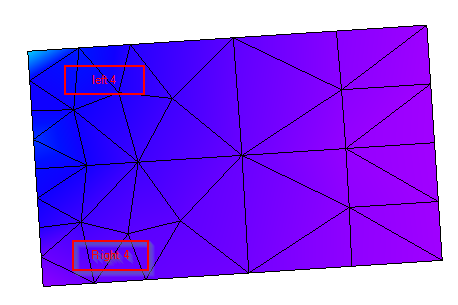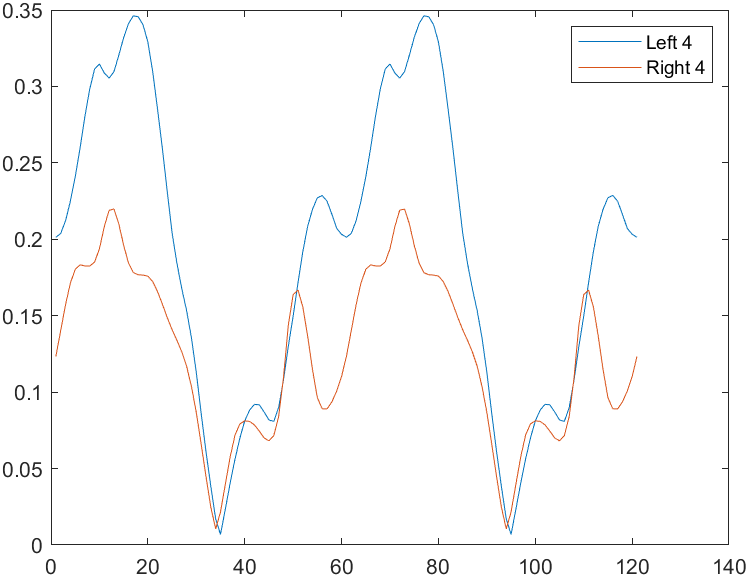

## speed List

1000~15000

skin Depth와 관련 

speedList=[1000:1000:15000];
skinDepth=

